clc;clear;close all;

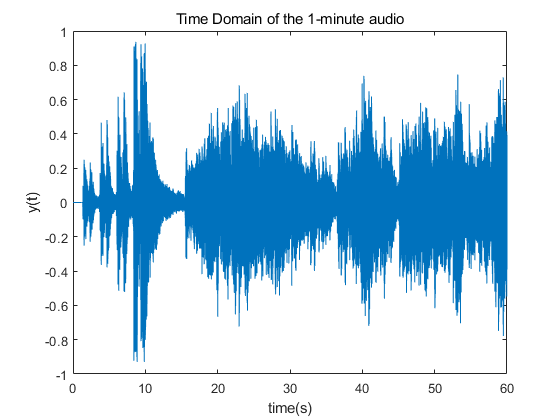

%% section 1
[yy,fs]=audioread("magnet.mp3");
N=60*fs;
y=yy(1:N,1);%get mono-channel audio
t=1:N;
plot(t./fs,y(t));
title("Time Domain of the 1-minute audio");
xlabel("time(s)");
ylabel("y(t)");

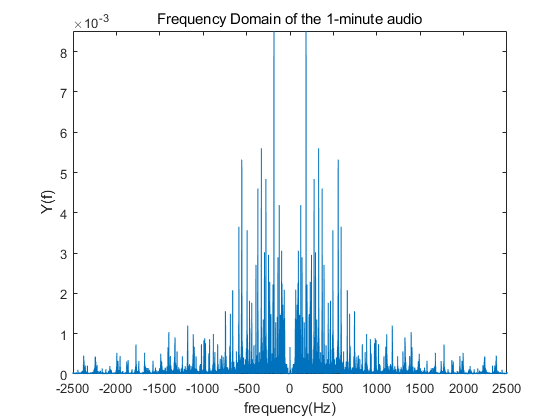

% do fft and show frequency domain
Y=fftshift(fft(y))/N;
f=(-N/2:N/2-1)*fs/N;
plot(f,abs(Y));
axis([-2500 2500 0 inf]);
title("Frequency Domain of the 1-minute audio");
xlabel("frequency(Hz)");
ylabel("Y(f)");

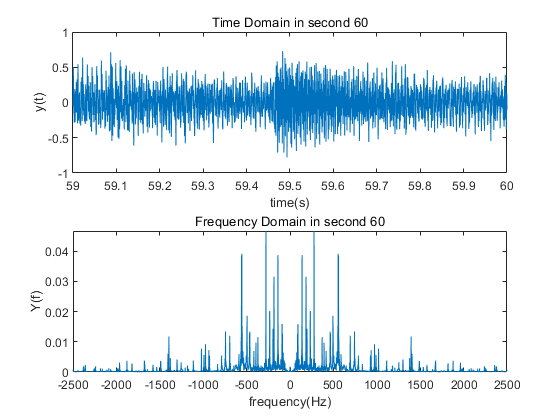

% section 2
figure
sound(y,fs);
tic;
for now=0:59 % 1-minute audio
    subplot(2,1,1);
    xt=1:fs;
    xa=y(now*fs+1:(now+1)*fs);
    plot(now+(xt./fs),xa(xt));
    title("Time Domain in second "+num2str(now+1));
    xlabel("time(s)");
    ylabel("y(t)");
    drawnow
    
    subplot(2,1,2);
    xY=fftshift(fft(xa))/fs;
    xf=-fs/2:fs/2-1;
    plot(xf,abs(xY));
    axis([-2500 2500 0 inf]);
    title("Frequency Domain in second "+num2str(now+1));
    xlabel("frequency(Hz)");
    ylabel("Y(f)");
    drawnow
    while toc < 1
        
    end
    tic;
end